# AcinoSet FTE Algorithm

[https://github.com/African-Robotics-Unit/AcinoSet](https://github.com/African-Robotics-Unit/AcinoSet)

### MatLab adaptation investigation

Kam Norton

Dev notes: 

- in the load_dlc_points_as_df function, need to make sure the MultiIndex functionality has been properly translated

- check over the lambdify section 

- The camera intrinsics, including those from OpenCV (K, D, T and R arrays) are tricky so check the data is handled correctly

addpath("Documents\AcinoSet\AcinoSetFTE\data\")
DATA_4_extCALIB = "Documents\AcinoSet\AcinoSetFTE\data\2019_03_09";
DATA_DIR = "Documents\AcinoSet\AcinoSetFTE\data\2019_03_09\lily\run";
DLC_CSV_PATH = "Documents\AcinoSet\AcinoSetFTE\src\dlc_df.csv";

#### Reconstruction Params

start_frame = 70;
end_frame = 170; %use -1 to reconstruct up to the last frame possible

% DLC p_cutoff - any points with likelihood < dlc_thresh are not trusted in optimization
dlc_thresh = 0.5; % change this only if the optimization result is unsatisfactory

#### Robust cost function

PLOT OF REDESCENDING, ABSOLUTE AND QUADRATIC COST FUNCTIONS, we use a redescending cost to stop outliers affecting the optimization negatively

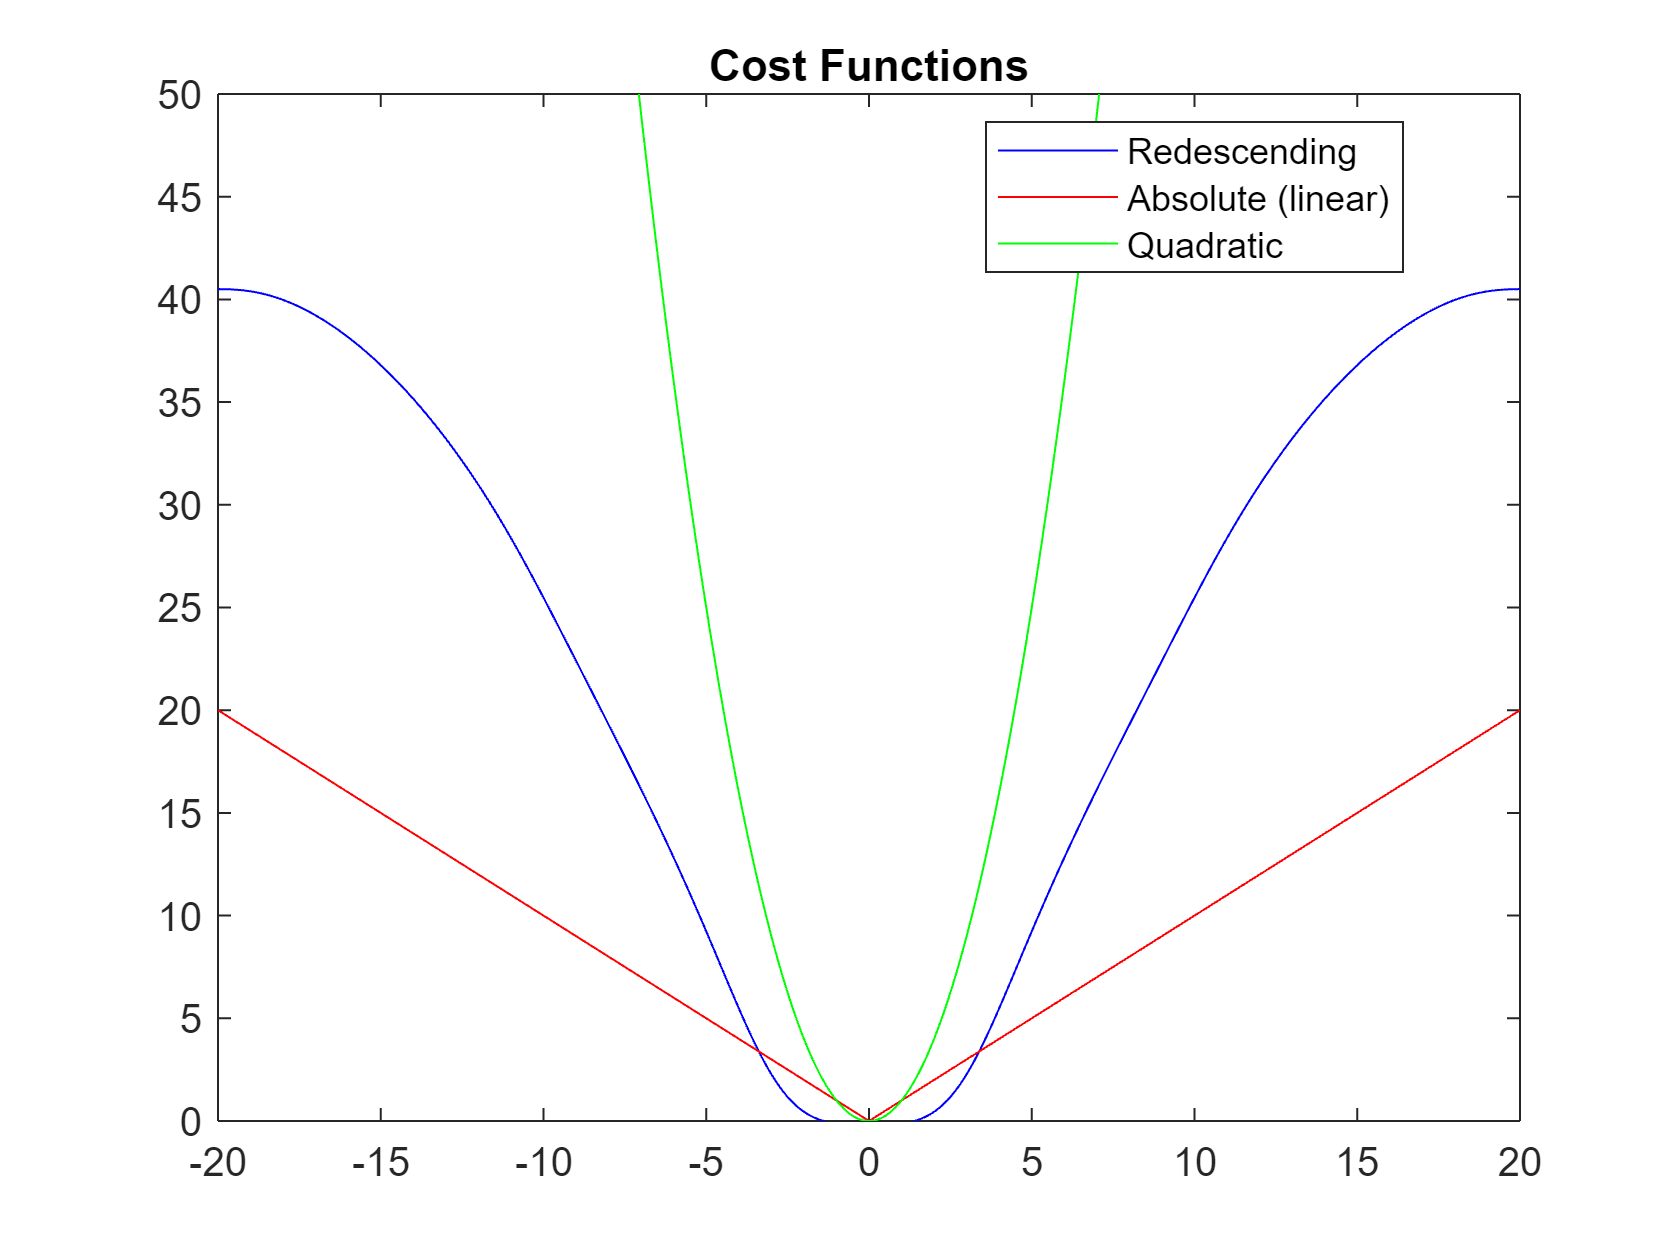

redesc_a= 3;
redesc_b= 10;
redesc_c= 20;
%Plot
r_x = -20:0.1:20;
r_y1 = zeros(size(r_x));
for i = 1:numel(r_x)
    r_y1(i) = redescending_loss(r_x(i), redesc_a, redesc_b, redesc_c);
end
r_y2 = abs(r_x);
r_y3 = (r_x).^2;

plot(r_x, r_y1, 'b', r_x, r_y2, 'r', r_x, r_y3, 'g')
title('Cost Functions');
ylim([0,50])
legend('Redescending', 'Absolute (linear)', 'Quadratic', Location='best')

## Optimisation

### Loading data etc

load video info

t0 = tic;
assert(isfolder(DATA_DIR),'Data directory not found: '+DATA_DIR);
OUT_DIR = fullfile(DATA_DIR, 'fte');
DLC_DIR = fullfile(DATA_DIR, 'dlc');
assert(isfolder(DLC_DIR),'Data directory not found: '+DLC_DIR);
if ~exist(OUT_DIR, 'dir')
    mkdir(OUT_DIR);
end
%%LOGGING??
projectdir = 'Documents\AcinoSet\AcinoSetFTE\data\2019_03_09\lily\run';

[ht,wid, fps, tot_frames] = getVideoInfo(projectdir);
res = [wid(1) ht(1)]; fps = fps(1); tot_frames = tot_frames(1);

assert(end_frame<=tot_frames, "End frame must be less than or equal to the total frames of the video");
assert(end_frame ~=0, "end_frame cannot be zero");
if end_frame<0
    end_frame = mod(end_frame,tot_frames)+1 %cyclic
end
assert(0<start_frame & start_frame<tot_frames, 'Start frame must be strictly between 0 and '+ tot_frames);
assert (0 <= dlc_thresh && dlc_thresh <= 1, 'dlc_thresh must be from 0 to 1');

Python to serialise params and store in json file: with open(os.path.join(OUT_DIR, 'reconstruction_params.json'), 'w') as f: json.dump(dict(start_frame=start_frame, end_frame=end_frame, dlc_thresh=dlc_thresh), f). Conversion to MATLAB done using chatGPT.

MATLAB code to serialise params and store in .json:

% Define the parameters to be stored in the JSON file
parameters = struct('start_frame', start_frame, 'end_frame', end_frame, 'dlc_thresh', dlc_thresh);

% Define the full path to the JSON file
json_file_path = fullfile(OUT_DIR, 'reconstruction_params.json');

% Serialize the parameters to JSON format and write to the file
json_str = jsonencode(parameters);
fid = fopen(json_file_path, 'w');
fprintf(fid, '%s', json_str);
fclose(fid); %close file after writing 

start_frame = start_frame - 1; % 0 based indexing

Symbolic vars, see functions for detail.

idx = get_pose_params();
symbols = keys(idx);
sym_list = sym(symbols); %works since the vars are stored as string
positions = get_3d_marker_coords(sym_list);



Lambdify symbolic fucntions - NB LOOK OVER IT

%func_map = {@sin, @cos, @(x) double(x)}; % not sure it is necessary since
%the cos and sine functions exist in matlab??
pose_to_3d = matlabFunction(positions, 'Vars', sym_list, 'File', 'pose_to_3d');

% Create lambdified functions for each row of positions
pos_funcs = cell(size(positions, 1), 1);
for i = 1:size(positions, 1)
    pos_funcs{i} = matlabFunction(positions(i, :), 'Vars', sym_list, 'File', ['pos_func_' num2str(i)]);
end
% pos_funcs

proj_funcs = {@pt3d_to_x2d, @pt3d_to_y2d};

Import camera and scene params

[K_arr, D_arr, R_arr, t_arr, cam_res, n_cams, scene_fpath] = find_scene_file(DATA_DIR,DATA_4_extCALIB, 1, '');
D_arr = reshape(D_arr, [], 4);
res = [res(1);res(2)];
assert(res(1) == cam_res(1) & res(2)== cam_res(2)) 
%reshape arrays for later - need to match python
K_arr = permute(reshape(K_arr.',3,3,n_cams), [2,1,3]);
R_arr = permute(reshape(R_arr.',3,3,n_cams), [2,1,3]);
t_arr = permute(reshape(t_arr.', [3, n_cams]), [2,1]);

Define constants

markers = get_markers();
R = 5; %measurement std deviation
Q = [4, 7, 5,...   % head position in inertial
    13, 9, 26,...  % head rotation in inertial
    32, 18, 12,... % neck
    43,...         % front torso
    10, 53, 34,... % back torso
    90, 43,...     % tail_base
    118, 51,...    % tail_mid
    247, 186,...   % l_shoulder, l_front_knee
    194, 164,...   % r_shoulder, r_front_knee
    295, 243,...   % l_hip, l_back_knee
    334, 149];      % r_hip, r_back_knee]
Q = double(Q).^2;


Load in data

sprintf('%s', 'Loading data');
fileList = dir(fullfile(DLC_DIR, '*.h5'));
%sort first, then process (rather than sort during processing)
T = struct2table(fileList);
sortedT = sortrows(T, 'name');
fileList = table2struct(sortedT);
fileNames = {fileList.name};
for i = 1:numel(fileNames)
    df_paths{i} = fullfile(DLC_DIR, fileNames{i});
end
%df_paths{i} = fullfile(DLC_DIR, fileNames{i})
points_2d_df = load_csv_to_table(DLC_CSV_PATH);
points_2d_df = change_camera_nums_matlab(points_2d_df)

points_2d_df = 32850×6 table
    camera    frame         marker            x         y       likelihood
    ______    _____    _________________    ______    ______    __________

      1         0      {'l_back_ankle' }    4.0309    812.19     0.058702 
      1         0      {'l_back_knee'  }     3.583    820.08      0.12125 
      1         0      {'l_back_paw'   }    12.097    836.22      0.20955 
      1         0      {'l_eye'        }    92.074    772.14     0.024167 
      1         0      {'l_front_ankle'}    52.667    835.85      0.11872 
      1         0      {'l_front_knee' }    4.0203    827.87      0.03385 
      1         0      {'l_front_paw'  }     76.24    820.36      0.48266 
      1         0      {'l_hip'        }    3.9774    796.17     0.013662 
      1         

### Optimisation code

disp('Initialising params & variables')

Initialising params & variables


m = optimproblem("Description",'Cheetah from measurements');
%don't need to define optim problem yet, only when we have obj function
%CLEAN THIS CODE
%%defining sets (rangeset in pyomo = array in matlab)
N = end_frame-start_frame;  %timesteps in trajectory
P = length(sym_list);          %number of pose params
L = length(markers);           %number of dlc labels per frame
C = n_cams;                 %cameras
D2 = 2;                     %dimensionality of image points
D3 = 3;                     %dimensionality of 3d points

%they are just ranges, not variables
ts = 1/fps; %timestep
N_range = 1:N;
P_range = 1:P;
L_range = 1:L;
C_range = 1:C;
D2_range = 1:D2;
D3_range = 1:D3;

%weights 
[val, meas] = init_meas_weights_and_measurements(N, C, L,R, points_2d_df, D2,start_frame, markers, dlc_thresh);
params = struct();
params.meas_err_weight = val;
params.meas = meas;
params.model_err_weight = 1/Q(P);

%variables
x = optimvar('x',N, P);     %position
dx = optimvar('dx', N, P);  %velocity
dx = optimvar('ddx', N, P); %acceleration
poses = optimvar('poses', N, L, D3);
slack_model = optimvar('slack_model', N, P);
slack_meas = optimvar('slack_meas',N, C, L, D2); 
slack_meas = 0; %initialise to 0

%initialisation
init_x    = zeros(N, P);
init_dx   = zeros(N, P);
init_ddx  = zeros(N, P);
frames = points_2d_df.frame;
filtered_points = points_2d_df(frames >= start_frame & frames < end_frame,:);
[est_nose_pos, est_nose_vel] = initialize_marker_3d(filtered_points, ...
    'nose', K_arr, D_arr, R_arr, t_arr, cam_res, 0.52,'plot', true)

        7316           1

Initializing nose's 3D points using an interim dlc_thresh of 0.51
Found 1784 pairwise points between camera 1 and 2
Found 1645 pairwise points between camera 2 and 3
Found 1054 pairwise points between camera 3 and 4
Found 1108 pairwise points between camera 4 and 5
Found 838 pairwise points between camera 5 and 6
Found 941 pairwise points between camera 6 and 1
        7370           1



Error using lsqcurvefit
Function value and YDATA sizes are not equal.

Error in MLX_FTE>EOM_curve_fit (line 608)
            [func_params(ax, :), ~] = lsqcurvefit(@(vari, t) fit_func(t, a,vari), func_params(ax, :), frames, pts_3d(:, ax));

Error in MLX_FTE>initialize_marker_3d (line 562)
 

outlier rejecting cost function

function out = func_step(start, x)
out = 1/(1+exp(-1*(x-start)));
end

function out = func_piece(start, end_var, x)
out = func_step(start, x) - func_step(end_var, x);
end

function output_cost = redescending_loss(err, a, b, c)
e = abs(err);
cost = 0;
cost = cost + (1-func_step(a,e))/(2*exp(2));
cost = cost + func_piece(a,b,e)*(a*e- (a^2)/2);
cost = cost + func_piece(b,c,e)*(a*b - (a^2)/2 + (a*(c-b)/2)*(1-((c-e)/(c-b))^2));
cost = cost + func_step(c,e)*(a*b-(a^2)/2 + (a*(c-b)/2));
output_cost = cost;
end

function [vidHeight,vidWidth, vidFPS, vidFrameNo] = getVideoInfo(projectdir)
%left out codec
dinfo = dir(fullfile(projectdir, '*.mp4'));
filenames = fullfile({dinfo.folder}, {dinfo.name});
numfiles = length(filenames);
vidRes = zeros(numfiles,2);
for K = 1 : numfiles
    thisfile = filenames{K};
    video = VideoReader(thisfile);

    vidWidth(K) = video.Width;
    vidHeight(K) = video.Height;
    vidFPS(K) = video.FrameRate;
    vidFrameNo(K) = video.NumFrames;
end
end

function params = get_pose_params()
    % Define symbolic variables
    syms x_0 y_0 z_0 phi_0 theta_0 psi_0 phi_1 theta_1 psi_1 theta_2 phi_3 theta_3 psi_3 ...
         theta_4 psi_4 theta_5 psi_5 theta_6 theta_7 theta_8 theta_9 theta_10 theta_11 ...
         theta_12 theta_13

    % Define the states cell array
    states = {'x_0', 'y_0', 'z_0', ...
              'phi_0', 'theta_0', 'psi_0', ...
              'phi_1', 'theta_1', 'psi_1', ...
              'theta_2', ...
              'phi_3', 'theta_3', 'psi_3', ...
              'theta_4', 'psi_4', ...
              'theta_5', 'psi_5', ...
              'theta_6', 'theta_7', ...
              'theta_8', 'theta_9', ...
              'theta_10', 'theta_11', ...
              'theta_12', 'theta_13'};

    % Create a dictionary mapping symbolic variables to indices
    params = containers.Map(states, 1:numel(states)); %where states is the 'key' and index is the value
end


function symsMatrix = get_3d_marker_coords(x)
%In python, Returns either a numpy array or a sympy Matrix of the 3D marker 
% coordinates (shape Nx3) for a given state vector x.
%In MATLAB: retuns a symbolic matrix of 3D Marker coordinates (Nx3) for a
% given state vector x.
idx = get_pose_params();
% Check if the first element of x is a symbolic expression
if isa(x(1), 'sym')
    func = @(x) sym(x); % Return the input as a symbolic variable
else
    func = @(x) double(x); % Convert the input to double precision
end

    %rotations
    RI_0  = rotz(x(idx('psi_0'))) * rotx(x(idx('phi_0'))) * roty(x(idx('theta_0')));         % head
    R0_I  = transpose(RI_0);
    RI_1  = rotz(x(idx('psi_1'))) * rotx(x(idx('phi_1'))) * roty(x(idx('theta_1'))) * RI_0 ; % neck
    R1_I  = transpose(RI_1);
    RI_2  = roty(x(idx('theta_2'))) * RI_1;                                                    % front torso
    R2_I  = transpose(RI_2);
    RI_3  = rotz(x(idx('psi_3'))) * rotx(x(idx('phi_3'))) * roty(x(idx('theta_3'))) * RI_2 ; % back torso
    R3_I  = transpose(RI_3);
    RI_4  = rotz(x(idx('psi_4'))) * roty(x(idx('theta_4'))) * RI_3;                           % tail base
    R4_I  = transpose(RI_4);
    RI_5  = rotz(x(idx('psi_5'))) * roty(x(idx('theta_5'))) * RI_4;                           % tail mid
    R5_I  = transpose(RI_5);
    RI_6  = roty(x(idx('theta_6'))) * RI_2;                                                    % l_shoulder
    R6_I  = transpose(RI_6);
    RI_7  = roty(x(idx('theta_7'))) * RI_6;                                                    % l_front_knee
    R7_I  = transpose(RI_7);
    RI_8  = roty(x(idx('theta_8'))) * RI_2;                                                    % r_shoulder
    R8_I  = transpose(RI_8);
    RI_9  = roty(x(idx('theta_9'))) * RI_8;                                                    % r_front_knee
    R9_I  = transpose(RI_9);
    RI_10 = roty(x(idx('theta_10'))) * RI_3;                                                   % l_hip
    R10_I = transpose(RI_10);
    RI_11 = roty(x(idx('theta_11'))) * RI_10;                                                  % l_back_knee
    R11_I = transpose(RI_11);
    RI_12 = roty(x(idx('theta_12'))) * RI_3;                                                   % r_hip
    R12_I = transpose(RI_12);
    RI_13 = roty(x(idx('theta_13'))) * RI_12;                                                  % r_back_knee
    R13_I = transpose(RI_13);

    %positions
    p_head          = [x(idx('x_0')), x(idx('y_0')), x(idx('z_0'))];

    p_l_eye         = p_head         + R0_I  * func(transpose([0, 0.03, 0]));
    p_r_eye         = p_head         + R0_I  * func(transpose([0, -0.03, 0]));
    p_nose          = p_head         + R0_I  * func(transpose([0.055, 0, -0.055]));

    p_neck_base     = p_head         + R1_I  * func(transpose([-0.28, 0, 0]));
    p_spine         = p_neck_base    + R2_I  * func(transpose([-0.37, 0, 0]));

    p_tail_base     = p_spine        + R3_I  * func(transpose([-0.37, 0, 0]));
    p_tail_mid      = p_tail_base    + R4_I  * func(transpose([-0.28, 0, 0]));
    p_tail_tip      = p_tail_mid     + R5_I  * func(transpose([-0.36, 0, 0]));

    p_l_shoulder    = p_neck_base    + R2_I  * func(transpose([-0.04, 0.08, -0.10]));
    p_l_front_knee  = p_l_shoulder   + R6_I  * func(transpose([0, 0, -0.24]));
    p_l_front_ankle = p_l_front_knee + R7_I  * func(transpose([0, 0, -0.28]));

    p_r_shoulder    = p_neck_base    + R2_I  * func(transpose([-0.04, -0.08, -0.10]));
    p_r_front_knee  = p_r_shoulder   + R8_I  * func(transpose([0, 0, -0.24]));
    p_r_front_ankle = p_r_front_knee + R9_I  * func(transpose([0, 0, -0.28]));

    p_l_hip         = p_tail_base    + R3_I  * func(transpose([0.12, 0.08, -0.06]));
    p_l_back_knee   = p_l_hip        + R10_I * func(transpose([0, 0, -0.32]));
    p_l_back_ankle  = p_l_back_knee  + R11_I * func(transpose([0, 0, -0.25]));

    p_r_hip         = p_tail_base    + R3_I  * func(transpose([0.12, -0.08, -0.06]));
    p_r_back_knee   = p_r_hip        + R12_I * func(transpose([0, 0, -0.32]));
    p_r_back_ankle  = p_r_back_knee  + R13_I * func(transpose([0, 0, -0.25]));

 symsMatrix = func([transpose(p_nose), transpose(p_r_eye), transpose(p_l_eye),...
                 transpose(p_neck_base), transpose(p_spine),...
                 transpose(p_tail_base), transpose(p_tail_mid), transpose(p_tail_tip),...
                 transpose(p_r_shoulder), transpose(p_r_front_knee), transpose(p_r_front_ankle),...
                 transpose(p_l_shoulder), transpose(p_l_front_knee), transpose(p_l_front_ankle),...
                 transpose(p_r_hip), transpose(p_r_back_knee), transpose(p_r_back_ankle),...
                 transpose(p_l_hip), transpose(p_l_back_knee), transpose(p_l_back_ankle)
                ]);
end

%%Projection functions
function [u, v] = pt3d_to_2d(x, y, z, K, D, R, t)
    x_2d = x*R(1,1) + y*R(1,2) + z*R(1,3) + t(1);
    y_2d = x*R(2,1) + y*R(2,2) + z*R(2,3) + t(2);
    z_2d = x*R(3,1) + y*R(3,2) + z*R(3,3) + t(3);
    % project onto camera plane
    a    = x_2d/z_2d;
    b    = y_2d/z_2d;
    % fisheye params
    r    = (a^2 + b^2 + 1e-12)^0.5;
    th   = pyo.atan(r);
   % distortion
    th_D = th * (1 + D(0)*th^2 + D(1)*th^4 + D(2)*th^6 + D(3)*th^8);
    x_P  = a*th_D/r;
    y_P  = b*th_D/r;
    u    = K(0,0)*x_P + K(0,2);
    v    = K(1,1)*y_P + K(1,2);
end

function u = pt3d_to_x2d(x, y, z, K, D, R, t)
[u,~] = pt3d_to_2d(x, y, z, K, D, R, t);

end

function v = pt3d_to_y2d(x, y, z, K, D, R, t)
[~,v] = pt3d_to_2d(x, y, z, K, D, R, t);

end

function [k_arr, d_arr, r_arr, t_arr, cam_res, n_cams, scene_files_end] = find_scene_file(dir_path,dir_extcalib,verbose, scene_fname) %scene_fname taken out of params
    if nargin < 2
        verbose = 1; % Default verbose value
    end
if isempty(scene_fname)
    file_list = ls(fullfile(dir_path,'cam*.mp4'));
    n_cams = size(file_list);
    n_cams = n_cams(1);
    if n_cams>0
        scene_fname = sprintf('%d_cam_scene_sba.json', n_cams);
    else 
        scene_fname = sprintf('%d_cam_scene*.json', (1:9));
    end
end
if ~isempty(dir_path) && ~strcmp(dir_path, fullfile('..','data'))
    %scene_fpath = fullfile(dir_extcalib, 'extrinsic_calib', scene_fname); 
    all_files = dir(fullfile(dir_extcalib, 'extrinsic_calib'));

    % Filter the files based on the condition ('before_corrections' not in scene_file)
    filtered_files = all_files(~contains({all_files.name}, 'before_corrections'));

    % Filter the files further based on the condition (scene_file == scene_fpath)
    filtered_files = filtered_files(strcmp({filtered_files.name}, scene_fname));

    % Sort the filtered files
    [~, idx] = sort({filtered_files.name});
    scene_files = filtered_files(idx);
    scene_files_end = scene_files(size(scene_files)).name;
    if ~isempty(scene_files)
         [k_arr, d_arr, r_arr, t_arr, cam_res] = load_scene(scene_files_end,0);
         [~,scene_fname,~] = fileparts(scene_files_end);
         n_cams = str2num(scene_fname(1)); %assuming scene_fname is of the form '[1-9]_cam_scene*'
    else 
        [k_arr, d_arr, r_arr, t_arr, cam_res, n_cams, scene_files_end]= find_scene_file(dir_path, scene_fname, verbose);
    end
else ENOENT = 2; % Error code for file not found (you may need to change this according to your error code)
    error('FileNotFoundError:ENOENT', ...
      'No such file or directory: %s', fullfile('extrinsic_calib', scene_fname));
end
end

function [k_arr, d_arr, r_arr, t_arr, cam_res] = load_scene(fpath, verbose)
    
    fid = fopen(fpath, 'r');
    data = jsondecode(fread(fid, inf, '*char')');
    fclose(fid);
    cam_res = data.camera_resolution;
    k_arr = [];
    d_arr = [];
    r_arr = [];
    t_arr = [];
    for idx = 1:numel(data.cameras)
        k_arr = [k_arr; data.cameras(idx).k];
        d_arr = [d_arr; data.cameras(idx).d];
        r_arr = [r_arr; data.cameras(idx).r];
        t_arr = [t_arr; data.cameras(idx).t];
    end
    k_arr = double(k_arr);
    d_arr = double(d_arr);
    r_arr = double(r_arr);
    t_arr = double(t_arr);
    
    if verbose
        fprintf('Loaded extrinsics from %s\n\n', fpath);
    end

end

function markers = get_markers()
markers = ["nose", "r_eye", "l_eye", "neck_base",...
        "spine", "tail_base", "tail1", "tail2",...
        "r_shoulder", "r_front_knee", "r_front_ankle",...
        "l_shoulder", "l_front_knee", "l_front_ankle",...
        "r_hip", "r_back_knee", "r_back_ankle",...
        "l_hip", "l_back_knee", "l_back_ankle"];
end



function data_table = load_csv_to_table(DLC_CSV_PATH)
    data_table = readtable(DLC_CSV_PATH, "FileType","delimitedtext", "Delimiter", ',');
end
                
function tableOut = change_camera_nums_matlab(table) 
camera = table.camera+1;
table = removevars(table, 'camera');
table = addvars(table, camera, Before=1);
tableOut = table;
end

function [val, meas] = init_meas_weights_and_measurements(n, c, l, R, points_2d_df,...
    d2, start_frame, markers, dlc_thresh)
    % Get likelihood from df
    meas = zeros(1);
    j=1;
    d_idx = ["x", "y"];
    for i = 1:height(points_2d_df)
        if points_2d_df.frame(i) == (n + start_frame - 1)
            if strcmp(string(points_2d_df.marker(i)), markers(l))
                if points_2d_df.camera(i) == c - 1
                    llh(j) = points_2d_df.likelihood(i);
                    meas_arr(j) = table2array(points_2d_df(i,d_idx(d2)));
                    j = j+1;
                end
            end
        end
    end
    meas = meas_arr;
    val = (llh > dlc_thresh) / R; % Branchless, R = std dev
end

function points_3d_df = get_pairwise_3d_points_from_df(points_2d_df, k_arr, d_arr, r_arr, t_arr, res,triangulate_func, verbose)
    n_cams = length(d_arr);
    for i=1:1:n_cams
        
        camera_pairs(i,:) = [mod(i,n_cams), mod(i+1, n_cams)];
        %camera 0 should be camera 6
        for k = 1:2
            if camera_pairs(i,k) ==0
                camera_pairs(i,k) =6;
            end
        end
    end
    df_pairs = table('Size', [0, 3], 'VariableTypes', {'double', 'double', 'double'}, 'VariableNames', {'x', 'y', 'z'});
    
    %get pairwise estimates
    
    for i = 1:length(camera_pairs)
        cam_a = camera_pairs(i,1);
        cam_b = camera_pairs(i,2);
        % Filter points_2d_df based on camera indices
        d0 = points_2d_df(double(points_2d_df.camera) == cam_a, :);
        d1 = points_2d_df(double(points_2d_df.camera) == cam_b, :);
        % Rename columns in d0 and d1 before merging
        % Rename 'x' and 'y' variables in d0
        d0.Properties.VariableNames{'x'} = 'x_a';
        d0.Properties.VariableNames{'y'} = 'y_a';

        % Rename 'x' and 'y' variables in d1
        d1.Properties.VariableNames{'x'} = 'x_b';
        d1.Properties.VariableNames{'y'} = 'y_b';
        
        intersection_df = innerjoin(d0,d1,'Keys', {'frame', 'marker'});

        if ~isempty(intersection_df)
            if verbose
                num_pw_pts = height(intersection_df);
                
                disp(['Found ',num2str(num_pw_pts), ' pairwise points between camera ', num2str(cam_a),  ' and ', num2str(cam_b)])
            end 
            % Extract points for cam_a and cam_b
            cam_a_points = [intersection_df.x_a, intersection_df.y_a];
            cam_b_points = [intersection_df.x_b, intersection_df.y_b];
            %triangulate
           
            points_3d = triangulate_func(cam_a_points, cam_b_points,k_arr(:,:,cam_a), d_arr(cam_a, :),...
                r_arr(:,:,cam_a), t_arr(cam_a,:),k_arr(:,:,cam_b), d_arr(cam_b,:),...
                r_arr(:,:,cam_b), t_arr(cam_b,:), res);
            % Add 3D points to intersection_df
            intersection_df.x = points_3d(:, 1);
            intersection_df.y = points_3d(:, 2);
            intersection_df.z = points_3d(:, 3);
           
            df_pairs = outerjoin(df_pairs, intersection_df, 'MergeKeys', true);  % Assuming 'df_pairs' is a table - joined along column
        else 
            if verbose
                disp(['No pairwise points between camera ', num2str(cam_a), ' and ', num2str(cam_b)]);
            end
        end
    end
    grouped_data = calculate_grouped_means(df_pairs);
    points_3d_df = grouped_data;
end

function pts_3d = triangulate_points(img_pts_1, img_pts_2, k1, d1, r1, t1, k2, d2, r2, t2,res)
    % Reshape image points
    pts_1 = reshape(img_pts_1, [], 1, 2);
    pts_2 = reshape(img_pts_2, [], 1, 2);

    % Undistort points
    pts_1 = undistortPoints(pts_1, k1, d1);
    pts_2 = undistortPoints(pts_2, k2, d2);

    % Combine rotation and translation matrices
    p1 = [r1, t1];
    p2 = [r2, t2];

    % Triangulate points
    pts_4d = triangulate(p1, p2, pts_1, pts_2);

    % Convert homogeneous coordinates to 3D points
    pts_3d = (pts_4d(:, 1:3) ./ pts_4d(:, 4))';
end

function [fit, fit_deriv] = initialize_marker_3d(points_2d_df, marker, k_arr, d_arr, r_arr, t_arr, res,dlc_thresh, plot, varargin)
    % Determine highest usable dlc_thresh
    dlc_thresh_step = 0.01;
    %dlc_thresh = dlc_thresh_step;
    frames = unique(points_2d_df.frame);
    tot_frames = numel(frames);
    num_frames = tot_frames;
    
     while num_frames == tot_frames
        pts_3d_df = get_pairwise_3d_points_from_df(points_2d_df(points_2d_df.likelihood > dlc_thresh, :), k_arr, d_arr, r_arr, t_arr, res, @triangulate_points_fisheye, 0);
        
        num_frames = numel(pts_3d_df(strcmp(string(pts_3d_df.marker), string(marker)),:));
        dlc_thresh = dlc_thresh + dlc_thresh_step;
    end
    
    dlc_thresh = dlc_thresh - 2 * dlc_thresh_step;
    disp(['Initializing ', marker, '''s 3D points using an interim dlc_thresh of ', num2str(dlc_thresh, '%.2f')]);
    % Run get_pairwise_3d_points_from_df once more with correct dlc_thresh
    pts_3d_df = get_pairwise_3d_points_from_df(points_2d_df(points_2d_df.likelihood > dlc_thresh,:), k_arr, d_arr, r_arr, t_arr, res, @triangulate_points_fisheye, 1);
       % Extract 3D points
    pts_3d = NaN(tot_frames, 3);
    
    marker_pts_3d = pts_3d_df(strcmp(string(pts_3d_df.marker), string(marker)), {'frame', 'x', 'y', 'z'});
    for i = 1:size(marker_pts_3d, 1)
        frame = marker_pts_3d.frame(i);
        x = marker_pts_3d.x(i);
        y = marker_pts_3d.y(i);
        z = marker_pts_3d.z(i);
        pts_3d(frame - frames(1) + 1, :) = [x, y, z];
    end

     % Perform curve fitting
    fit_order = 3;  % Default value for fit_order
    if nargin > 8
        fit_order = varargin{1};  % Override if provided
    end
    [fit, fit_deriv] = EOM_curve_fit(pts_3d, frames, fit_order);

    % Plot if requested
    if plot
        title_str = [num2str(fit_order), 'th Order Fit for ', upper(marker)];
        plot_marker_3d(pts_3d, frames, fit, title_str);
    end
    
end

function [fit, fit_deriv] = EOM_curve_fit(pts_3d, frames, fit_order)
    import matlabFunction.*;
    import matlabFunction.deriv.*;
    import matlabFunction.series.*;

    % Check if frames are provided
    if nargin < 2
        frames = 1:size(pts_3d, 1);
    end

    % Check and set the default value for fit_order
    if nargin < 3
        fit_order = 3;
    end

    % Define symbolic variables
    syms t a vari;
    symbols = [t a];
    num_axes = size(pts_3d, 2);
    n = fit_order + 1;

    % Generate the equation of motion series
    fit_func_str = a;
    func_params = zeros(num_axes, 1);

    % Loop to build the fit function string and initialize parameters
    for order = 1:n
        if order > 1
            symbols(end + 1) = sym(char(symbols(end)) + 1);
            fit_func_str = fit_func_str + vari*sym(char(symbols(end)))^order;
            func_params = [func_params, zeros(num_axes, 1)];
        end
        fit_func = matlabFunction(fit_func_str, 'Vars', [t, a,vari]);

        % Perform curve fitting
        for ax = 1:num_axes
            [func_params(ax, :), ~] = lsqcurvefit(@(vari, t) fit_func(t, a,vari), func_params(ax, :), frames, pts_3d(:, ax));
        end
    end

    % Remove the constant term
    symbols(2) = [];
    
    % Create the derivative of the fit function
    fit_func_deriv = diff(fit_func_str, t);
    fit_func_deriv = matlabFunction(fit_func_deriv, 'Vars', [t, sym(char(syms(2:end)))]);

    % Calculate the fit and its derivative
    fit = zeros(size(pts_3d));
    fit_deriv = zeros(size(pts_3d));
    for ax = 1:num_axes
        fit(:, ax) = fit_func(frames, func_params(ax, :));
        fit_deriv(:, ax) = fit_func_deriv(frames, func_params(ax, 2:end));
    end
end


function pts_3d = triangulate_points_fisheye(img_pts_1, img_pts_2, k1, d1, r1, t1, k2, d2, r2, t2, res)
    % Reshape image points
    % pts_1 = reshape(img_pts_1, [], 1, 2);
    % pts_2 = reshape(img_pts_2, [], 1, 2);
    pts_1 = reshape(img_pts_1, [],2);
    pts_2 = reshape(img_pts_2, [],2);
    %https://www.mathworks.com/help/vision/ref/stereoparametersfromopencv.html
   
    focal_length = [abs(k1(1, 1)) abs(k1(2,2))];
    principal_point = abs([k1(1, 3) k1(2,3)]);
    % Create cameraIntrinsics object
    intrinsics = cameraIntrinsics(focal_length, principal_point, res); %took out radial distortion

    % Undistort image points - tried fisheye but not working 
    pts_1_undistorted = undistortPoints(pts_1, intrinsics);
    pts_2_undistorted = undistortPoints(pts_2, intrinsics);
    
    % Combine rotation and translation matrices
    p1 = [r1; t1]; p2 = [r2; t2];
    %camMatrix = [rotationMatrix; translationVector] × K.
    %stereoParams = stereoParametersFromOpenCV(k1,d1,k2,d2,r2,t2,res);
    % Triangulate points
    pts_4d = triangulate(pts_1_undistorted, pts_2_undistorted, p1, p2);%p1); %'PointsToHomogeneous', true);
    %pts_3d = pts_4d(:, 1:3) ./ pts_4d(:, 4);
    pts_3d = pts_4d;
end

% function points_3d_df = calculate_grouped_means(df_pairs)
%     % Horizontally concatenate 'frame' and 'marker' as rows
%     combined_frame_marker = horzcat(df_pairs.frame, df_pairs.marker);
% 
%     % Find unique combinations of 'frame' and 'marker'
%     [groups, ~, group_indices] = unique(combined_frame_marker, 'rows');
% 
%     % Calculate the mean coordinates for each group
%     grouped_means = splitapply(@mean, [df_pairs.x, df_pairs.y, df_pairs.z], group_indices);
% 
%     % Create a table with 'frame', 'marker', and mean coordinates
%     points_3d_df = array2table([groups, grouped_means], ...
%                                 'VariableNames', {'frame', 'marker', 'mean_x', 'mean_y', 'mean_z'});
% end
function points_3d_df = calculate_grouped_means(df_pairs)
    % Convert 'frame' and 'marker' to cell arrays
   
    frame_cell = num2cell(df_pairs.frame);
    marker_cell = num2cell(df_pairs.marker);
    
    % Combine 'frame' and 'marker' cells into a cell array
    combined_frame_marker_cell = [frame_cell, marker_cell];
    
    % Convert cell array to a table
    combined_frame_marker_table = cell2table(combined_frame_marker_cell, ...
                                              'VariableNames', {'frame', 'marker'});
    
    % Find unique combinations of 'frame' and 'marker'
    [groups, ~, group_indices] = unique(combined_frame_marker_table, 'rows');
    
    % Verify the dimensions of group_indices
    disp(size(group_indices));
    
    % Calculate the mean coordinates for each group separately
    mean_x = splitapply(@mean, df_pairs.x, group_indices);
    mean_y = splitapply(@mean, df_pairs.y, group_indices);
    mean_z = splitapply(@mean, df_pairs.z, group_indices);
    
    % Create a table with 'frame', 'marker', and mean coordinates
    points_3d_df = table(groups.frame, groups.marker, mean_x, mean_y, mean_z, ...
                         'VariableNames', {'frame', 'marker', 'x', 'y', 'z'});
end


